clear vars
gitHistoryTable = readtable('bootstrap-output.xlsx');

## The top contributors according to git history data

Enter how many of the top contributors you would like to view into the textbox below. Beware the max number of contributors printed to the right.

contributors = categorical(gitHistoryTable.name);
[commitsPerContr, contributors] = histcounts(contributors);
[sortedCommits, newIndices] = sort(commitsPerContr, "descend");
sortedContributors = contributors(newIndices);
disp(['Max number of contributors: ', num2str(length(sortedContributors))])

Max number of contributors: 1276


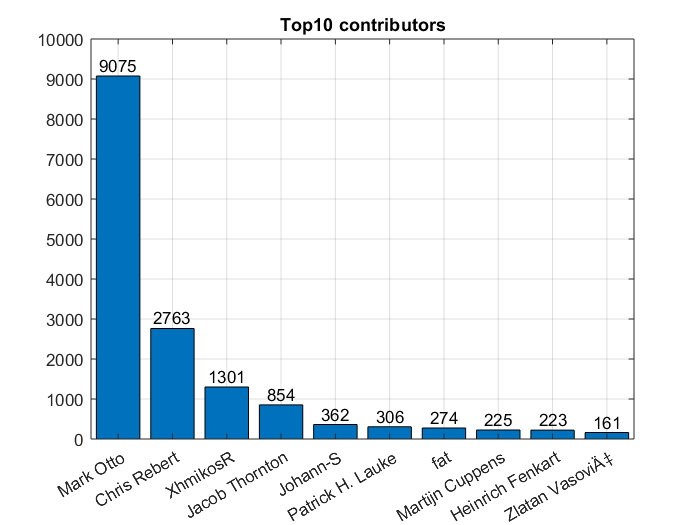

x = 10;
x = round(x);
topxUsers = sortedContributors(1:x);

sortedContributors = categorical(topxUsers, topxUsers);
sortedCommits = sortedCommits(1:x);

bar(sortedContributors, sortedCommits);

text(1:length(sortedCommits), sortedCommits, categorical(sortedCommits'), "vert", "bottom", "horiz", "center");
grid on

s = strcat('Top ', num2str(x), ' contributors');
title(s)

## The number of contributors, commits and commits per contributor.

numContributors = length(contributors);
numCommits = length(gitHistoryTable.commit);
avgCommits = numCommits/numContributors;
disp(['Number of contributors: ', num2str(numContributors)])

Number of contributors: 1276


disp(['Number of commits: ', num2str(numCommits)])

Number of commits: 19057


disp(['Average commits per contributor: ', num2str(avgCommits)])

Average commits per contributor: 14.935


## Commits over time

months = categorical(gitHistoryTable.date);
[commitsPerMonth, months] = histcounts(months)

commitsPerMonth =           10          59          25         223         254         121          83         665         357         254         144         154         176         271         143         127         233         237         220         167         214         217         550        1025         343         165         565         440         280         368         126         298         452         140         151         238         394         250         190         195         295          93          57         540         172         193         287         257         333          79


months = 1×103 cell array
    {'2011-04-01'}    {'2011-06-01'}    {'2011-07-01'}    {'2011-08-01'}    {'2011-09-01'}    {'2011-11-01'}    {'2011-12-01'}    {'2012-01-01'}    {'2012-02-01'}    {'2012-03-01'}    {'2012-04-01'}    {'2012-06-01'}    {'2012-07-01'}    {'2012-08-01'}    {'2012-09-01'}    {'2012-11-01'}    {'2012-12-01'}    {'2013-01-01'}    {'2013-02-01'}    {'2013-03-01'}    {'2013-04-01'}    {'2013-06-01'}    {'2013-07-01'}    {'2013-08-01'}    {'2013-09-01'}    {'2013-11-01'}    {'2013-12-01'}    {'2014-01-01'}    {'2014-02-01'}    {'2014-03-01'}    {'2014-04-01'}    {'2014-06-01'}    {'2014-07-01'}    {'2014-08-01'}    {'2014-09-01'}    {'2014-11-01'}    {'2014-12-01'}    {'2015-01-01'}    {'2015-02-01'}    {'2015-03-01'}    {'2015-04-01'}    {'2015-06-01'}    {'2015-07-01'}    {'2015-08-01'}    {'2015-09-01'}    {'2015-11-01'}    {'2015-12-01'}    {'2016-01-01'}    {'2016-02-01'}    {'2016-03-01'}    {'2016-04-01'}    {'2016-06-01'}    {'2016-07-01'}    {'2016-08-01'}  

monthDates = datetime(months)

monthDates = 1×103 datetime array
   01-Apr-2011   01-Jun-2011   01-Jul-2011   01-Aug-2011   01-Sep-2011   01-Nov-2011   01-Dec-2011   01-Jan-2012   01-Feb-2012   01-Mar-2012   01-Apr-2012   01-Jun-2012   01-Jul-2012   01-Aug-2012   01-Sep-2012   01-Nov-2012   01-Dec-2012   01-Jan-2013   01-Feb-2013   01-Mar-2013   01-Apr-2013   01-Jun-2013   01-Jul-2013   01-Aug-2013   01-Sep-2013   01-Nov-2013   01-Dec-2013   01-Jan-2014   01-Feb-2014   01-Mar-2014   01-Apr-2014   01-Jun-2014   01-Jul-2014   01-Aug-2014   01-Sep-2014   01-Nov-2014   01-Dec-2014   01-Jan-2015   01-Feb-2015   01-Mar-2015   01-Apr-2015   01-Jun-2015   01-Jul-2015   01-Aug-2015   01-Sep-2015   01-Nov-2015   01-Dec-2015   01-Jan-2016   01-Feb-2016   01-Mar-2016   01-Apr-2016   01-Jun-2016   01-Jul-2016   01-Aug-2016   01-Sep-2016   01-Nov-2016   01-Dec-2016   01-Jan-2017   01-Feb-2017   01-Mar-2017   01-Apr-2017   01-Jun-2017   01-Jul-2017   01-Aug-2017   01-Sep-2017   01-Nov-2017   01-Dec-2017   01-Jan-2018   01-Feb-2018

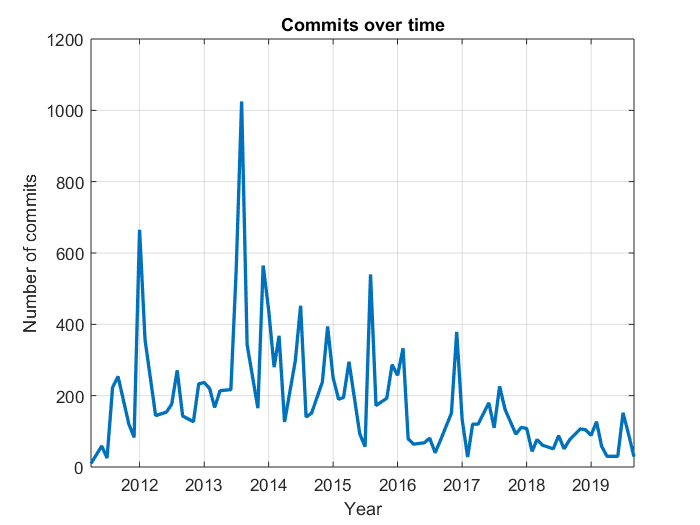

months = categorical(months, months);
quarters = [];
commitsPerQuarter = [];

plot(monthDates, commitsPerMonth, 'LineWidth', 2);
title('Commits over time');
grid on;
xlabel('Year');
ylabel('Number of commits');

GUI

% s = get(0, 'ScreenSize')
% w = s(3)
% h = s(4)
% startX = w/2 - w/2/2;
% startY = h/2 - h/2/2;
% f = figure('Visible','off','Position', [startX, startY, w/2, h/2]);
% 
% f.Visible = 'on';

CallGraph